clear all;

## Constant length lever

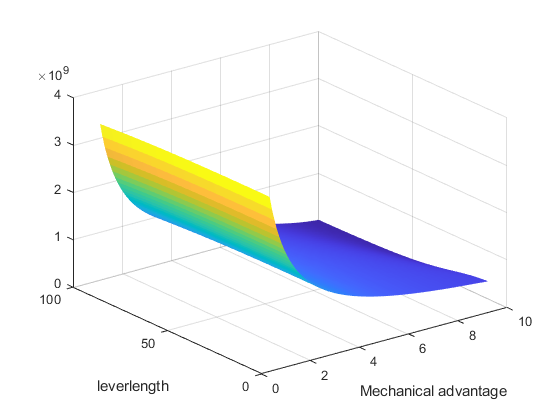

Ea = 13.4E10; %elastic modulus ceramic
Em = 210E9; %elastic modulus steel

MA0 = 1.1; MA1 = 10;
MAstep = 0.1;
lever0 = 10; lever1 = 100;
leverstep = 1;
MA = [MA0:MAstep:MA1]; %mechanical advantage B/A (for whole integer numbers)
levers = [lever0:leverstep:lever1]*1E-3;
[Y,X] = meshgrid(lever0:leverstep:lever1,MA0:MAstep:MA1);

L1 = length(MA);
L2 = length(levers);
%Prealocating space for matrices
A = zeros(L1,L2); B = zeros(L1,L2);
h_a = zeros(L1,L2); %actuator height
h_l = zeros(L1,L2); %lever height
Ca = zeros(L1,L2); %stiffness actuator
C_tot = zeros(L1,L2);
Ua = zeros(L1,L2); Ul = zeros(L1,L2);

S_out = 10; %micrometers
S0 = 3.3; %micrometers
h0 = 2E-3; %m

w_a = 15E-3; %width of the actuator

leverThic = 45E-3; %m

totalHeight = 90E-3; %m

for i=1:L1
    for j=1:L2
        
        LeverLength = levers(j);
        Ma = 1 / MA(i); %Mechanical advantage A/B (easier for computations)
        A(i,j) = LeverLength*Ma/(1+Ma); 
        B(i,j) = LeverLength/(1+Ma);
        h_a(i,j) = (1/Ma) * (S_out/S0 + 1) * h0;
        h_l(i,j) = totalHeight - h_a(i,j);
       
        Ca(i,j) = Ea * w_a^2 / h_a(i,j);
        I = h_l(i,j)^3 * leverThic;
        Ua(i,j) = 0.5/Ca(i,j);
        Ul(i,j) =  ( B(i,j)*A(i,j) )/( 6 * (Ma^2)*LeverLength * Em * I ) * (LeverLength^2 - B(i,j)^2 - A(i,j)^2);
        cl(i,j) = 3 * Em * I/(LeverLength^3);
        
        C_tot2(i,j) = (1./Ca(i,j) + 1./cl(i,j))^-1;
        C_tot(i,j) = 0.5 * (Ua(i,j) + Ul(i,j) )^-1;
    end
end

figure 
clf
s1 = surf(X,Y,C_tot);
s1.EdgeColor = 'none';


xlabel("Mechanical advantage")
ylabel("leverlength")

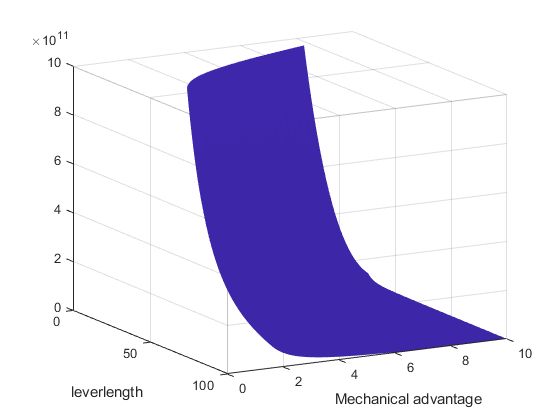

figure 
clf

s1 = surf(X,Y,1./Ul);
s1.EdgeColor = 'none';
xlabel("Mechanical advantage")
ylabel("leverlength")
zlim([0 1E12])

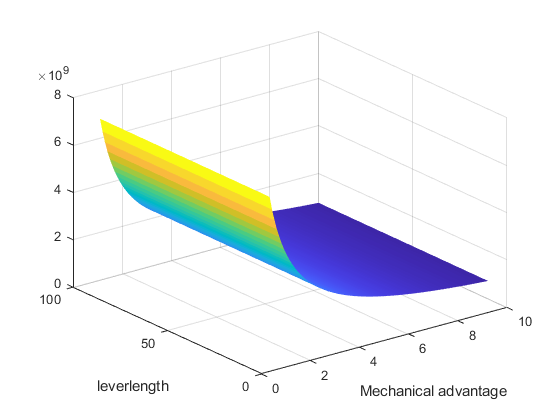

figure 
clf

s1 = surf(X,Y,1./Ua);
s1.EdgeColor = 'none';

xlabel("Mechanical advantage")
ylabel("leverlength")

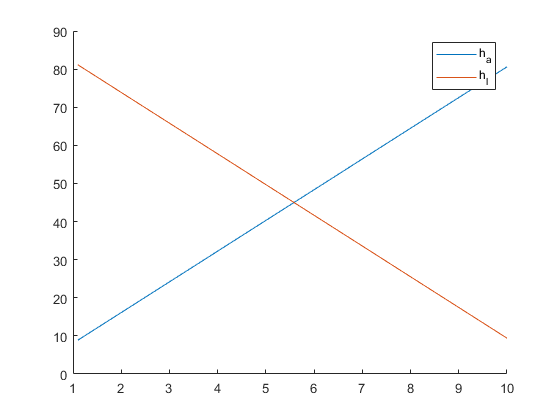

figure()
clf;
hold on
plot(MA,h_a(:,1)*1E3)
plot(MA,h_l(:,1)*1E3)
legend('h_a','h_l')
ylim([0 90])

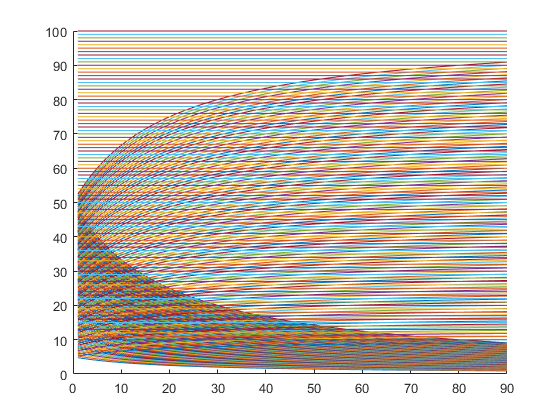


figure()
clf
hold on
plot(A*1E3)
plot(B*1E3)